# Savings upon re-aiming in visuomotor adaptation - Morehead et al

clear; clc; cd('/Users/duncan/Dropbox/BIOMS/Qualifying/Exam/Morehead/Code')


## Make targets

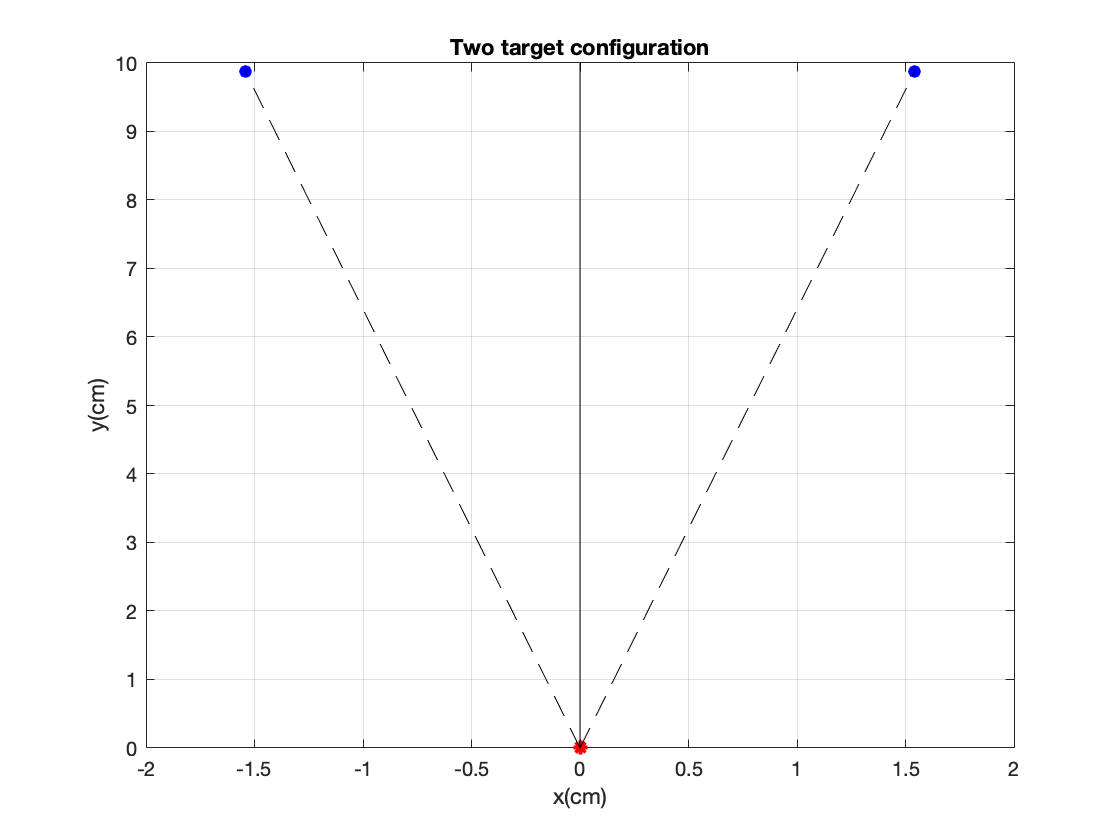

% Two targets 
CW_targ = [10*cos(30),10*sin(30)];
CCW_targ = [10*cos(-30),10*sin(-30)];
figure;
plot(0,0, 'r*', 'markersize', 5, 'linewidth', 2)
hold on 
plot(-CW_targ(1), -CW_targ(2), 'bo', 'markerfacecolor', 'b')
plot(CCW_targ(1), CCW_targ(2), 'bo', 'markerfacecolor', 'b')
xlabel('x(cm)')
ylabel('y(cm)')
grid on 
line([0 -CW_targ(1)], [0 -CW_targ(2)], 'linestyle', '--', 'color', 'k')
line([0 CCW_targ(1)], [0 CCW_targ(2)], 'linestyle', '--', 'color', 'k')
line([0 0], [0 10], 'color', 'k')
title('Two target configuration')

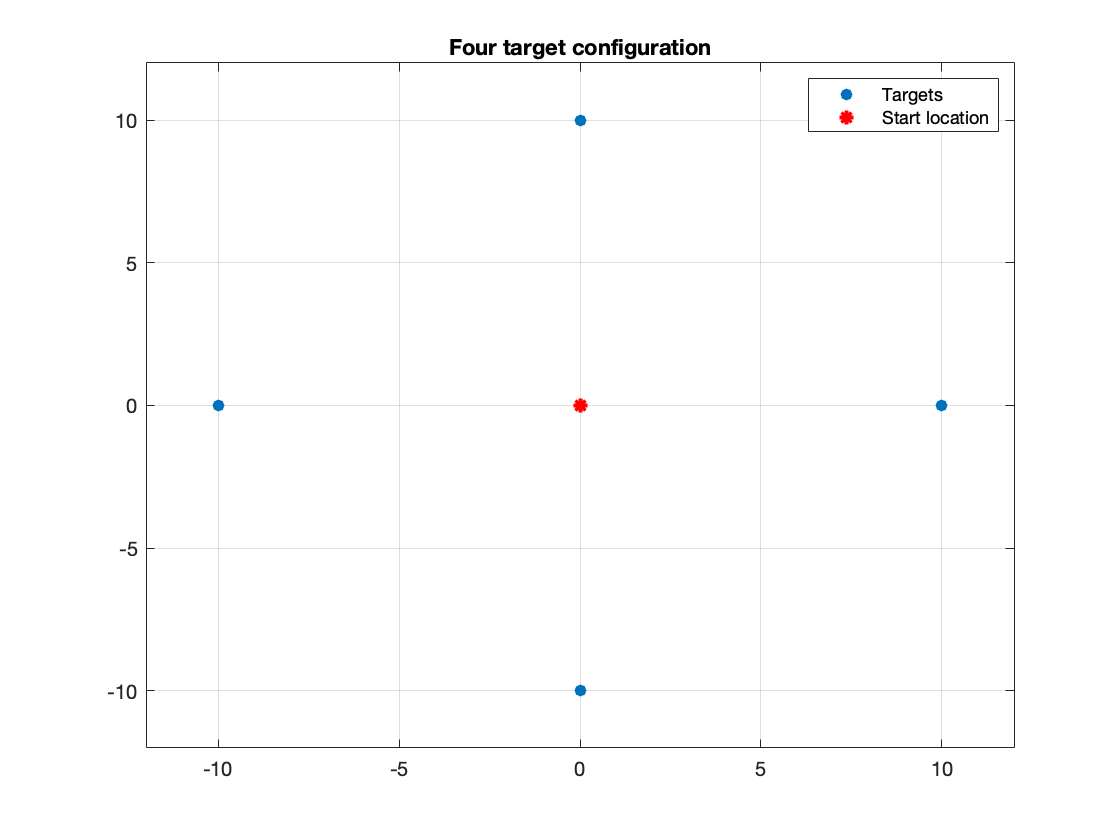


% Four targets 
four_targs = [0,10;10,0;-10,0;0,-10];
figure;
scatter(four_targs(:,1), four_targs(:,2), 'filled')
hold on 
plot(0,0,'r*', 'markersize', 5, 'linewidth', 2)
axis([-12 12 -12 12])
box on 
grid on 
legend('Targets', 'Start location')
title('Four target configuration')

## Fitting exponential functions

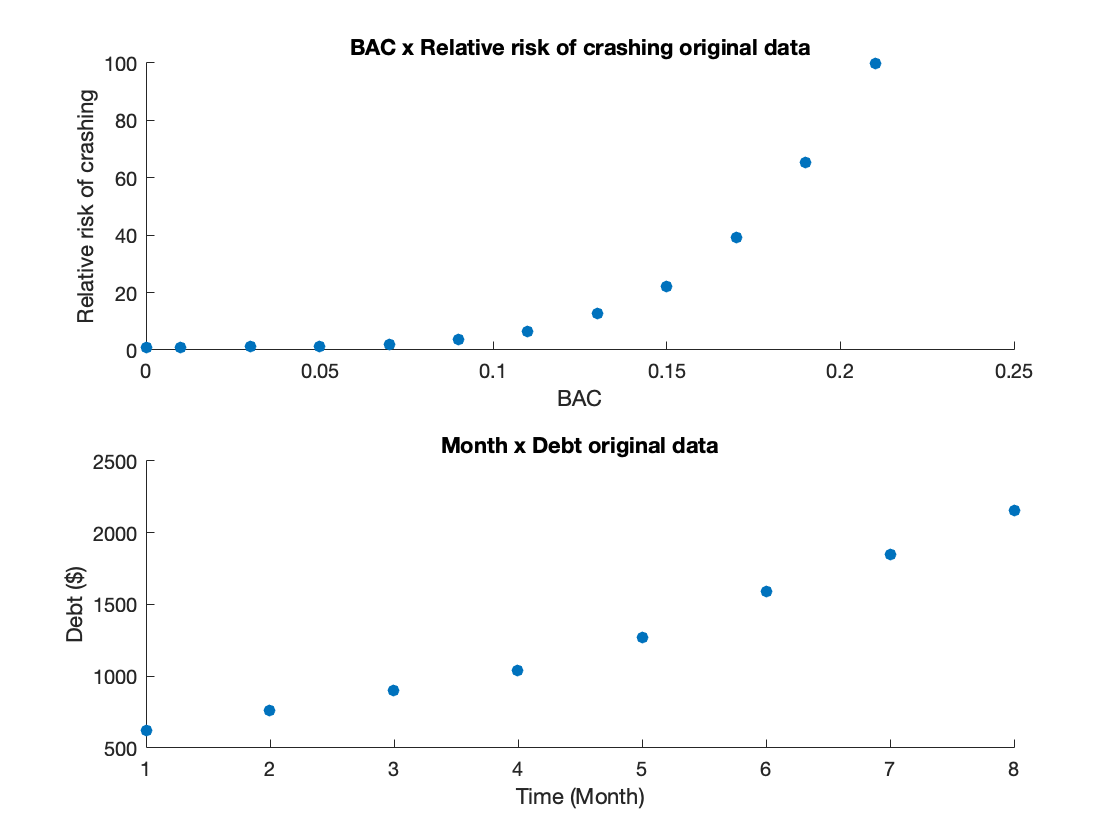

% Example data sets
BAC_crashrisk = [0,1];
BAC_crashrisk(2:12,1) = 0.01:0.02:0.21;
BAC_crashrisk(2:12,2) = [1.03,1.06,1.38,2.09,3.54,6.41,12.6,22.1,39.05,65.32,99.78];

month_debt(:,1) = [1;2;3;4;5;6;7;8];
month_debt(:,2) = [620;761.88;899.8;1039.92;1270.63;1589.04;1851.31;2154.92];


% Plot original data 
figure;
subplot(2,1,1);scatter(BAC_crashrisk(:,1), BAC_crashrisk(:,2), 'filled')
title('BAC x Relative risk of crashing original data')
xlabel('BAC')
ylabel('Relative risk of crashing')
subplot(2,1,2); scatter(month_debt(:,1), month_debt(:,2), 'filled')
title('Month x Debt original data')
xlabel('Time (Month)')
ylabel('Debt ($)')

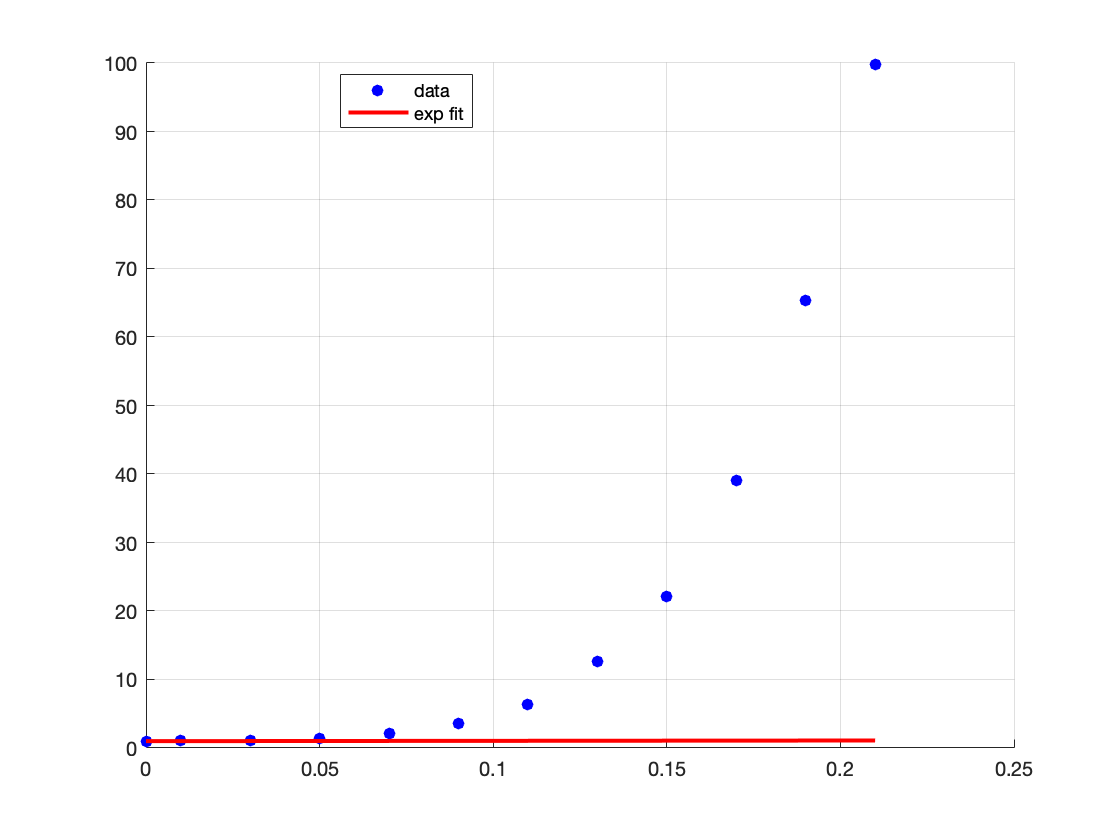

% Test function 
[~,a,b,BAC_crashriskfit] = fitexp(BAC_crashrisk, 'y');

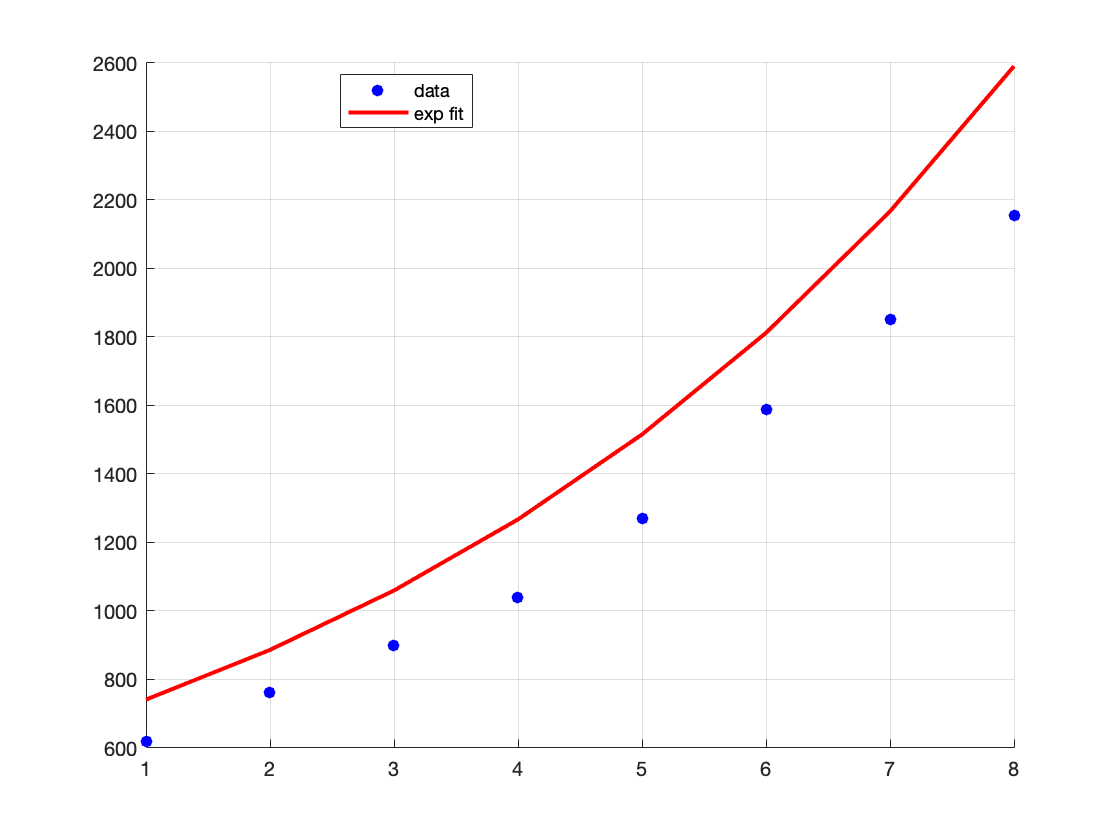

[~,a,b,month_debtfit] = fitexp(month_debt, 'y');

function [yhat,a,b,data_wfit] = fitexp(data, plot_yn)

% INPUT
% data: x,y in columns 
% plot_yn: plot data with fit, y/n?

% Formula = y = ab^x
sz = size(data);
if sz(2) > sz(1)
    data = data';
    sz = size(data);
end
a = data(1,2);

divis = nan(sz(1)-1,1);
for i = 1:sz(1)-1
    divis(i) = data(i+1,2) / data(i,2);
    divis(i) = round(divis(i), 3, 'significant');
end
b = nanmean(divis);

yhat = nan(sz(1),1);
for i = 1:sz(1)
        yhat(i) = a*b^(data(i,1));
end

data_wfit = [data(:,1:2),yhat];

if strcmp(plot_yn, 'y')
    figure;
    scatter(data(:,1), data(:,2), 'b', 'filled')
    hold on 
    grid on 
    plot(data_wfit(:,1), data_wfit(:,3), 'r-', 'linewidth', 2)
    legend('data', 'exp fit', 'location', 'best')
end

% OUTPUT:
% y: y values of fit line
% a: y-intercept 
% b: average slope(?)
% data: x,y,yhat

end


